% Just working through model-free RL for a simple cartpole to help tune
% hyperparameters 

% Setting up environment
cartpoleEnv = rlPredefinedEnv("CartPole-Discrete")

cartpoleEnv =   CartPoleDiscreteAction with properties:

                  Gravity: 9.8000
                 MassCart: 1
                 MassPole: 0.1000
                   Length: 0.5000
                 MaxForce: 10
                       Ts: 0.0200
    ThetaThresholdRadians: 0.2094
               XThreshold: 2.4000
      RewardForNotFalling: 1
        PenaltyForFalling: -5
                    State: [4×1 double]


cartpoleObsInfo = getObservationInfo(cartpoleEnv)

cartpoleObsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "CartPole States"
    Description: "x, dx, theta, dtheta"
      Dimension: [4 1]
       DataType: "double"


cartpoleActInfo = getActionInfo(cartpoleEnv)

cartpoleActInfo =   rlFiniteSetSpec with properties:

       Elements: [-10 10]
           Name: "CartPole Action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


rng(0)

% Setting up DQN neural network
cartpoleNet = [
    featureInputLayer(cartpoleObsInfo.Dimension(1))
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(length(cartpoleActInfo.Elements))];

cartpoleNet = dlnetwork(cartpoleNet);
summary(cartpoleNet)

   Initialized: true

   Number of learnables: 142

   Inputs:
      1   'input'   4 features



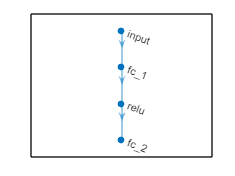

% Displaying DQN neural network
plot(cartpoleNet)

% Creating the agent
critic = rlVectorQValueFunction(cartpoleNet,cartpoleObsInfo,cartpoleActInfo);
getValue(critic,{rand(cartpoleObsInfo.Dimension)})

ans = 2×1 single column vector
   -0.2257
    0.4299


cartpoleAgent = rlDQNAgent(critic);
getAction(cartpoleAgent,{rand(cartpoleObsInfo.Dimension)})

ans = 1×1 cell array
    {[10]}


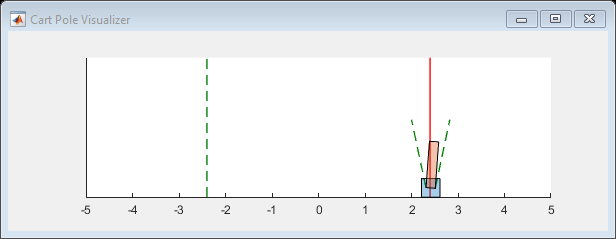

% Training agent

cartpoleAgent.AgentOptions.UseDoubleDQN = false;
cartpoleAgent.AgentOptions.TargetSmoothFactor = 1;
cartpoleAgent.AgentOptions.TargetUpdateFrequency = 4;
cartpoleAgent.AgentOptions.ExperienceBufferLength = 1e5;
cartpoleAgent.AgentOptions.MiniBatchSize = 256;
cartpoleAgent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-3;
cartpoleAgent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=500, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=480); 

plot(cartpoleEnv)
trainingStats = train(cartpoleAgent,cartpoleEnv,trainOpts);

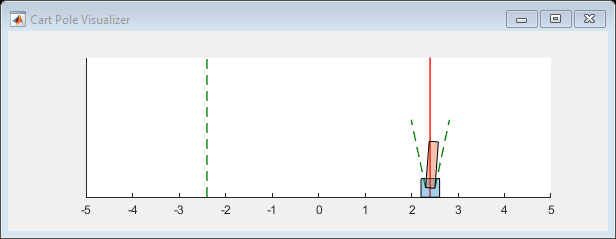

% Simulate environment
plot(cartpoleEnv)
simOptions = rlSimulationOptions(MaxSteps=5000);
experience = sim(cartpoleEnv,cartpoleAgent,simOptions);